# Figures 2-4, Evaporation data

## Set input files

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Figures\Figures2to4\data\input'
load('Bflat30min.mat')
load('BflatEdCov.mat')
load('Bflat_30minLEann_23561011131517.mat')
load('BLM93_AirPresCor.mat')
load('BLM93C.mat')
load('BLM34_complete.mat')

cd ../output/

## Replace ANN values with eddy covariance flux values, where available.

Test = outerjoin(Bflat_30minLEann_23561011131517,bflatEdCov,'Type','left');
Test.logical = Test.Evaporation_mm30min > -3 ;
Test.logical2 = Test.logical == 0;
% Test2 = Test;
% Test2 = sortrows(Test2,'logical','descend');
% Test2 = Test2(1:2393,:);
Test.Evaporation_mm30min(isnan(Test.Evaporation_mm30min)) = 0;
Test.LEann_prctile50 = Test.LEann_prctile50.*Test.logical2 + Test.Evaporation_mm30min.*Test.logical;
Bflat_30minLEann_23561011131517.LEann_prctile50 = Test.LEann_prctile50;
clear Test

## Calculate potential evaporation

p = Bflat30min.Pressure_kPa; %*1000; %*1000; Pressure at 10m Pa
ws2m = Bflat30min.WindSpeed_kph./3.6; %m/s - average windspeed 2 m 
T2m = Bflat30min.AirTemp1_C; %temp in C 
RH2m = Bflat30min.RelHumidity; %RH - relative humidity
Rn = Bflat30min.NetRad_Wm2; %W/m^2 - net radiation 

#### Estimation of G - for Daily Averages, G can be estimated at 0, Allen 1998, Equation 42, page 54

Hg = Rn*0;%W/m^2 - GHF % Soil heat flux - not available - which is why only using daily averages. 
%Constants
T_o = 273.15; %Reference temp K
R_v = 461.5; %J-K/kg gas constant for water vapor
R_da = 287.06; %J-K/kg gas constant for dry air
cp = 1013; %J/kg/K
lambda = 2.454e6; %J/kg latent heat of vaporization (1 kg = 1 mm/m^-2)
epsilon = 0.622; %Ratio of gas constants

## Inputs

rho2m = p./(R_da*(T2m+273.15)); %p = rho*R*Tv ideal gas law - density of dry air
gamma = cp*(p)/(epsilon*lambda); %psychrometric constant (pa K-1)

#### Saturation Vapour Pressure - Equation 11, page 36 of Allen et al, 1998

e_s = 0.6108*exp((17.27*T2m)./(T2m+237.3)); %Saturation vapor pressure at temperature T (Pa)

#### Actual Vapor Pressure - Equation 19 or equation 54, Page 39-40 of Allen, 1998

e = (RH2m/100).*e_s; %Actual Vapor pressure (kPa)

#### Slope of Saturation vapour pressure curve (delta) [kPa C-1] - Equation 13/page 37 of Allen 1998

delta =(4096*(0.6108*exp((17.27*T2m)./(T2m+237.3))))./((T2m+237.3).^2); 
Bflat30min.e_ActualVaporPressure = e;
Bflat30min.e_s_SaturationVaporPressure = e_s;

### Malek 1990 Penman (Equation A4)

Bflat30min.PET_m = delta./(delta + gamma).*(Rn + Hg) + gamma./(delta + gamma).*15.36.*(0.75 + 0.0115*ws2m).*(e_s - e);
%1 watt = 1 J/S - convert Watts to number of seconds in a day to get Joules then divide by lambda to get the evaporation value.  
Bflat30min.PET_m = Bflat30min.PET_m*60*60*24/lambda; %Convert to mm/day

### Malek 1990 Penman (equation A4 adapted for water activity [CN]) slight decrease in PE from orginal output. 

beta = 0.74; %Calculated value for water acticity (see supplemental files) (normal water is 1)
Bflat30min.PET_m_CN = delta./(delta + gamma/beta).*(Rn + Hg) + gamma./(delta + gamma/beta).*15.36.*(0.75 + 0.0115*ws2m).*(e_s - e/beta);
Bflat30min.PET_m_CN = Bflat30min.PET_m_CN*60*60*24/lambda; %Convert to mm/day
BflatDaily = retime(Bflat30min, "daily", "mean");

### Plot PE over time

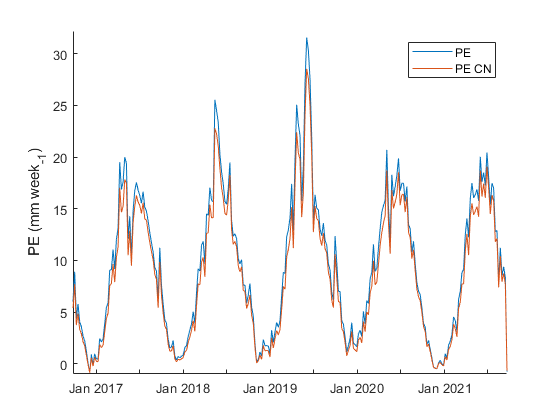

BflatWeekly = retime(BflatDaily,"weekly",'sum');
figure
hold on 
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m, 'displayname', 'PE')
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN, 'displayname', 'PE CN')
% plot(BflatDaily.Date_Time_MDT ,BflatDaily.PPT_mm, 'displayname', 'PPT')
ylabel('PE (mm week_-_1)');
ylim([-1,32.2])
xlim(BflatWeekly.Date_Time_MDT([1,end]))
legend

## Define datasets: daily mean and daily sum dataset.

%Define albedo
Bflat30min.SolarRad_Wm2Logical = Bflat30min.SolarRad_Wm2 > 10; % 10 watt threshold for night
Bflat30min.SolarRad_Wm2_filtered = Bflat30min.SolarRad_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min.OutRad_sw_Wm2_filtered = Bflat30min.OutRad_sw_Wm2.*Bflat30min.SolarRad_Wm2Logical;
Bflat30min = removevars(Bflat30min, 'SolarRad_Wm2Logical');

BflatDaily = retime(Bflat30min, "daily", "mean");
BflatDailySum = retime(Bflat30min, "daily", 'sum');
BflatDailySum.albedo = BflatDailySum.OutRad_sw_Wm2_filtered./BflatDailySum.SolarRad_Wm2_filtered;

#### Adjusting albedo for earlier period - linear shift down so alligns with records better (one of the radiometers dirty?) then smooth the data - rougher than later equipment.

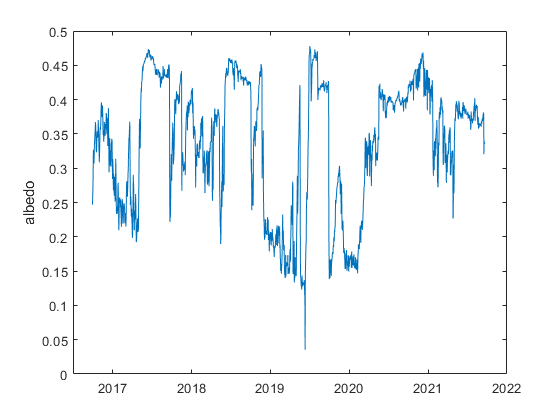

% BflatDailySum.albedo(1:251) = BflatDailySum.albedo(1:251) -0.07;
BflatDailySum.albedo(239:251) = NaN ; %anamolously high albedo right before the equipment replaced with new radiometer.
BflatDailySum.albedo = fillmissing(BflatDailySum.albedo,'linear');
BflatDailySum.albedo(1:251) = smoothdata(BflatDailySum.albedo(1:251),'movmean','SmoothingFactor',0.06,...
    'SamplePoints',BflatDaily.Date_Time_MDT(1:251));


BflatDaily.albedo = filloutliers(BflatDailySum.albedo,'linear','movmean',days(59),...
    'SamplePoints',BflatDailySum.Date_Time_MDT);
BflatDaily.albedoLogical = BflatDaily.albedo > 0.37; %threshold value for dessicated stage classification, rexamined the data - outsid of the calibration period this looks representative of des surface
BflatDaily.PPT_mm = BflatDailySum.PPT_mm; %Note I am adding this so I can use one daily value
bflatEdCovDaily = retime(bflatEdCov, "daily", "sum");

figure
plot(BflatDaily.Date_Time_MDT, BflatDaily.albedo)
ylabel('albedo')


LEANNDaily = retime(Bflat_30minLEann_23561011131517, "daily", "sum");
LEANNDailyCalibrationPeriod = LEANNDaily([595:672],:);

PETCalibration = outerjoin(LEANNDailyCalibrationPeriod,BflatDaily,'Type','left');
clear BflatDailySum beta cp delta Hg e e_s epsilon gamma lambda p RH2m rho2m R_v Rn R_da T_o T2m ws2m 

# Plot 1, PET and albedo against PE

figure
tiledlayout flow

## PET against Eddy cov

nexttile
hold on 
f = fit(PETCalibration.PET_m_CN, PETCalibration.LEann_prctile50, 'exp1');
plot(f, PETCalibration.PET_m_CN, PETCalibration.LEann_prctile50)
ylabel('Eddy Cov Evap')
xlabel('PET')

## PET against Eddy cov

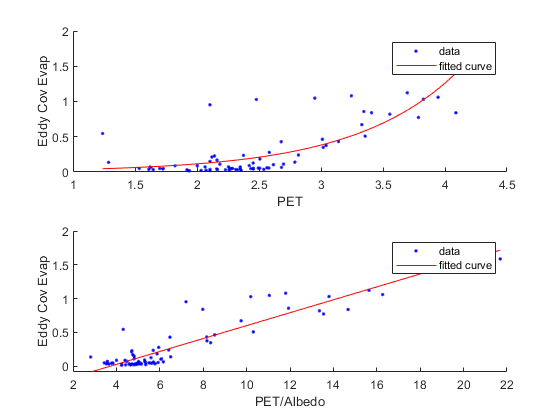

nexttile
hold on 
f = fit(PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50, 'poly1');
plot(f, PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50)
ylabel('Eddy Cov Evap')
xlabel('PET/Albedo')

### Whole dataset albedo calibration

poly = polyfit(PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50, 1);
BflatDaily.PET_m_CN_albedoKc = poly(1)*(BflatDaily.PET_m_CN./BflatDaily.albedo);

### Trimmed dataset albedo calibration

#### Wet period

PETCalibrationFlooded = sortrows(PETCalibration,'LEann_prctile50','descend');
PETCalibrationFlooded([26:end],:) = [];
poly = polyfit(PETCalibrationFlooded.PET_m_CN./PETCalibrationFlooded.albedo, PETCalibrationFlooded.LEann_prctile50, 1);
BflatDaily.PET_m_CN_albedoKcTrimmedDatasetWET = poly(1)*(BflatDaily.PET_m_CN./BflatDaily.albedo);

constantKc = poly(1) %Flooded period Kc to be divided by albedo

constantKc = 0.0750

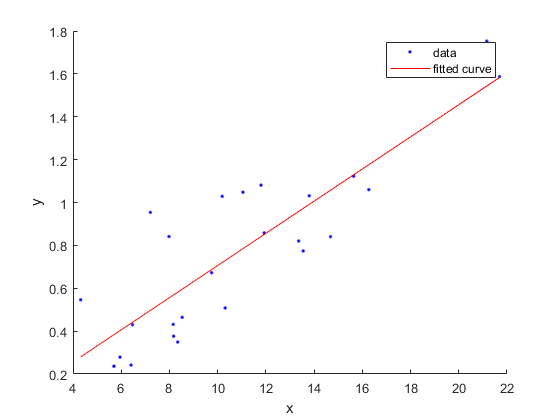


figure  
hold on 
[f, error] = fit(PETCalibrationFlooded.PET_m_CN./PETCalibrationFlooded.albedo, PETCalibrationFlooded.LEann_prctile50, 'poly1');
plot(f, PETCalibrationFlooded.PET_m_CN./PETCalibrationFlooded.albedo, PETCalibrationFlooded.LEann_prctile50) %, 'displayname', 'wetperiod')

#### Dry period

PETCalibrationDesiccation = sortrows(PETCalibration,'albedoLogical','descend');
PETCalibrationDesiccation(58:end,:) =[];
poly = polyfit(PETCalibrationDesiccation.PET_m_CN./PETCalibrationDesiccation.albedo, PETCalibrationDesiccation.LEann_prctile50, 1);
BflatDaily.PET_m_CN_albedoKcTrimmedDatasetDRY = (0.0788+0.0351)/2*(BflatDaily.PET_m_CN./BflatDaily.albedo);
poly(1) %dessication stage kc with continuous scaling 
PETCalibrationDesiccation = sortrows(PETCalibration,'albedoLogical','descend');
PETCalibrationDesiccation(58:end,:) =[];
%%Remove rain days with low albedo to get a lower bounds estimate of evaporation.
PETCalibrationDesiccation = sortrows(PETCalibrationDesiccation,'LEann_prctile50','ascend');
PETCalibrationDesiccation = PETCalibrationDesiccation(1:52,:);

[f, error] = fit(PETCalibrationDesiccation.PET_m_CN./PETCalibrationDesiccation.albedo, PETCalibrationDesiccation.LEann_prctile50, 'poly1');
plot(f, PETCalibrationDesiccation.PET_m_CN./PETCalibrationDesiccation.albedo, PETCalibrationDesiccation.LEann_prctile50) %, 'displayname', 'dryperiod')
title('dry and wet surface fits')
legend('location', 'northwest')
ylabel('Eddy Cov Evap')
xlabel('PET/Albedo')
DesKC = mean(PETCalibrationDesiccation.LEann_prctile50)./mean(PETCalibrationDesiccation.PET_m_CN) %dry surface Kc
yline(DesKC);

#### Combined

BflatDaily.albedoLogical2  = BflatDaily.albedoLogical == 0;

BflatDaily.PET_m_CN_albedoPiecewise2 = BflatDaily.PET_m_CN_albedoKcTrimmedDatasetWET.*BflatDaily.albedoLogical2 + BflatDaily.PET_m_CN_albedoKcTrimmedDatasetDRY.*BflatDaily.albedoLogical;
BflatDaily.PET_m_CN_albedoKcTrimmedDatasetDRY = DesKC*(BflatDaily.PET_m_CN);

## Exclude the period of rain from this model to make it a more effective lower limit.

BflatDaily.PET_m_CN_albedoPiecewise = BflatDaily.PET_m_CN_albedoKcTrimmedDatasetWET.*BflatDaily.albedoLogical2 + BflatDaily.PET_m_CN_albedoKcTrimmedDatasetDRY.*BflatDaily.albedoLogical;

## Results #1 figure (Figure 2)

figure;
tiledlayout (6,2)
ax = gca; 
ax.FontSize = 10;

#### Evaporation and PPT data

nexttile ([2,2])

% title("Calibration Period",'fontsize',14)
yyaxis left
hold on
% plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN,"-", 'color', [0.0350 0.0780 0.1840], 'linewidth', 2, ...
%     'displayname', "E_a")
plot(LEANNDaily.Date_Time_MDT, LEANNDaily.LEann_prctile50,"--", 'color', [0.6350 0.0780 0.1840], 'linewidth', 2, ...
    'displayname', "E (eddy covariance)")
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN_albedoPiecewise,":", 'color', [0 0.4470 0.7410], ...
    'linewidth', 2,  "DisplayName", "E_eLow (K_c constant when dry)")
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN_albedoPiecewise2,"-.", 'color', ...
    [0.9290 0.6940 0.1250], 'linewidth', 2,  "DisplayName", "E_eHigh (K_c scaled when dry)")
ylabel('evaporation (mm d^-^1)','fontsize',10)

yyaxis right
bar(BflatDaily.Date_Time_MDT, BflatDaily.PPT_mm, 0.3,'displayname', "Precipitation")
ylabel('PPT (mm d^-^1)','fontsize',10)
ylim([0,6.5])

set(gca, 'YDir','reverse')

lgnd = legend('location', "northoutside",'fontsize',10);
set(lgnd,'color','none');
hold off

xlim(bflatEdCovDaily.Date_Time_MDT([13,end]))
xticklabels({})

set(gca, 'XTick', (bflatEdCovDaily.Date_Time_MDT([13]) : 7 : bflatEdCovDaily.Date_Time_MDT([end])));

#### Potential evaporation and albedo

nexttile ([1,2])
yyaxis left
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN,"-",'linewidth', 2, ...
    'displayname', "PE")
ylabel('PE (mm d^-^1)','fontsize',10)

yyaxis right
plot(BflatDaily.Date_Time_MDT, BflatDaily.albedo, 'linewidth', 2, 'displayname', 'albedo')
ylabel('albedo','fontsize',10)
xlim(bflatEdCovDaily.Date_Time_MDT([13,end]))
xticklabels({})
set(gca, 'XTick', (bflatEdCovDaily.Date_Time_MDT([13]) : 7 : bflatEdCovDaily.Date_Time_MDT([end])));

#### Groundwater level

nexttile ([1,2])
BLM93 = retime(BLM93, 'daily', 'mean');

yyaxis left
hold on 
% figure
plot(BLM93.Date_Time_MDT, -BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*100,'linewidth', 2,'displayname', 'BLM-93')
yline(0)
ylabel('water depth (cm)','fontsize',10)
ylim([-11,5])

yyaxis right
plot(BflatDaily.Date_Time_MDT, BflatDaily.SoilTemp_C,'linewidth', 2)
ylabel('ground temp. (^oC)','fontsize',10)
% ylim([732,748])

xlim(bflatEdCovDaily.Date_Time_MDT([13,end]))

tileSpacing = 'compact';
Padding = 'compact';
print('Fig2atocETCalibrationPeriod', '-bestfit','-dpdf') 

## Supplemental figure - vapor pressure deficit, humidity

figure
tiledlayout flow
nexttile ([1,2])

plot(BflatDaily.Date_Time_MDT, BflatDaily.RelHumidity,'linewidth', 2)
ylabel('relative humidity (%)')
xlim(BflatDaily.Date_Time_MDT([1,end]))
nexttile ([1,2])

% plot(BflatDaily.Date_Time_MDT, BflatDaily.e_s_SaturationVaporPressure-BflatDaily.e_ActualVaporPressure,'linewidth', 2)
hold on
beta = 0.71;
plot(BflatDaily.Date_Time_MDT, BflatDaily.e_s_SaturationVaporPressure - BflatDaily.e_ActualVaporPressure./beta,'linewidth', 2)
yline(0)
ylabel('Vapor Pressure Deficit')

#### Calibration E, PE, and albedo

figure; 
tiledlayout (2,2) %'flow'
ax = gca; 
ax.FontSize = 10;


#### Albedo vs Ea

nexttile 
[f, error] = fit(PETCalibration.albedo, PETCalibration.LEann_prctile50, 'poly1'); %other fits 'log1' and 'poly1' less good
md1 = fitlm(PETCalibration.albedo, PETCalibration.LEann_prctile50);
md1.Rsquared.Ordinary
hold on 
plot(f, PETCalibration.albedo, PETCalibration.LEann_prctile50)
scatter(PETCalibration.albedo, PETCalibration.LEann_prctile50, 15, "diamond",'filled', 'blue')
ylabel('E_a (mm d^-^1)','fontsize',10)
xlabel('albedo','fontsize',10)
legend('off')

#### PE/Albedo vs. Ea

nexttile 
[f, error] = fit(PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50, 'poly1');
md1 = fitlm(PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50);
md1.Rsquared.Ordinary
hold on 
plot(f, PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50)
scatter(PETCalibration.PET_m_CN./PETCalibration.albedo, PETCalibration.LEann_prctile50, 15, "diamond",'filled', 'blue')
ylabel('E_a (mm d^-^1)','fontsize',10)
xlabel('PE (mm d^-^1) / albedo','fontsize',10)
ylim([0,2])
legend('off')

nexttile 
nexttile 
TileSpacing = 'compact';
Padding = 'compact';
print('Fig2dtoeETCalibrationPeriodAlbedoPE', '-bestfit','-dpdf') %'-bestfit' -fillpage

#### Statistics - contrast methods across dessication and flooding stages

#### Mean evaporation rate - dessication calibration period

PETCalibrationDesiccation = sortrows(PETCalibration,'albedoLogical','descend');
PETCalibrationDesiccation(58:end,:) =[];
PETCalibrationDesiccation = outerjoin(PETCalibrationDesiccation,BflatDaily,'Type','left');

mean(PETCalibrationDesiccation.PET_m_CN_PETCalibrationDesiccation)
mean(PETCalibrationDesiccation.LEann_prctile50)
mean(PETCalibrationDesiccation.PET_m_CN_albedoPiecewise) 
mean(PETCalibrationDesiccation.PET_m_CN_albedoPiecewise2)

### Potential ET during flooding stage - calibration period

PETCalibrationFlooded = outerjoin(PETCalibrationFlooded,BflatDaily,'Type','left');

mean(PETCalibrationFlooded.PET_m_CN_PETCalibrationFlooded)
% median(PETCalibrationFlooded.PET_m_CN_PETCalibrationFlooded)
mean(PETCalibrationFlooded.LEann_prctile50)
mean(PETCalibrationFlooded.PET_m_CN_albedoPiecewise)
mean(PETCalibrationFlooded.PET_m_CN_albedoPiecewise2)
clear PETCalibrationDesiccation PETCalibrationFlooded

BflatDaily = outerjoin(BflatDaily,LEANNDaily,'Type','left');
save("bflatDaily_Evap.mat", 'BflatDaily')

## ANN adjustment, adjusting down if greater than PE and 2x greater than piecewise continous albedo calibration. 

### Replace with average of 50 and 25 percentiles, run filter agian. Fill high points with 25 percentile, run again. Then fill points with albedoLogical2 datapoints. 

BflatDaily.logical = BflatDaily.LEann_prctile50 > BflatDaily.PET_m_CN; %ID areas where LeANN > Potential evap
BflatDaily.logical2 = (BflatDaily.LEann_prctile50 > BflatDaily.PET_m_CN_albedoPiecewise2*2).*BflatDaily.albedoLogical2; %ID areas where LeANN > Potential evap during Flooding stage
BflatDaily.logical = BflatDaily.logical + BflatDaily.logical2;
BflatDaily.logicalGood  = BflatDaily.logical == 0; 
BflatDaily.logicalBad = BflatDaily.logicalGood == 0;

BflatDaily.LEann_prctile50_modified = BflatDaily.LEann_prctile50.*BflatDaily.logicalGood + (BflatDaily.LEann_prctile50+BflatDaily.LEann_prctile25)/2.*BflatDaily.logicalBad;
BflatDaily.logical = BflatDaily.LEann_prctile50_modified > BflatDaily.PET_m_CN; %ID areas where LeANN > Potential evap
BflatDaily.logical2 = (BflatDaily.LEann_prctile50_modified > BflatDaily.PET_m_CN_albedoPiecewise2*4).*BflatDaily.albedoLogical2; %ID areas where LeANN > Potential evap during Flooding stage
BflatDaily.logical = BflatDaily.logical + BflatDaily.logical2;
BflatDaily.logicalGood  = BflatDaily.logical == 0; 
BflatDaily.logicalBad = BflatDaily.logicalGood == 0;
BflatDaily.LEann_prctile50_modified = BflatDaily.LEann_prctile50_modified.*BflatDaily.logicalGood + (BflatDaily.LEann_prctile25).*BflatDaily.logicalBad;

BflatDaily.logical = BflatDaily.LEann_prctile50 > BflatDaily.PET_m_CN; %ID areas where LeANN > Potential evap
BflatDaily.logicalGood  = BflatDaily.logical == 0; 
BflatDaily.logicalBad = BflatDaily.logicalGood == 0;
BflatDaily.LEann_prctile50_modified = BflatDaily.LEann_prctile50_modified.*BflatDaily.logicalGood + (BflatDaily.PET_m_CN_albedoPiecewise2).*BflatDaily.logicalBad;

BflatDaily.logical = [];
BflatDaily.logical2 = [];
BflatDaily.logicalGood = [];
BflatDaily.logicalBad = [];
BflatDaily.albedoLogical = [];
BflatDaily.albedoLogical2 = [];


### QA-QC qaulitative check

figure
hold on
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN, 'displayname', 'PET')
plot(BflatDaily.Date_Time_MDT, BflatDaily.PET_m_CN_albedoPiecewise2, 'displayname', 'E_eHigh')
plot(LEANNDaily.Date_Time_MDT, LEANNDaily.LEann_prctile50, 'displayname', 'E_eANN original')
plot(BflatDaily.Date_Time_MDT, BflatDaily.LEann_prctile50_modified, 'displayname', 'E_eANN modified')
ylabel('mm evap/day')
xlabel('day')
ylim([-0.2,5])
legend

#### Make weekly means for the data

LEANNWeekly = retime(Bflat_30minLEann_23561011131517, "weekly", 'mean');
BflatWeekly = retime(BflatDaily, "weekly", 'mean');

#### redoing these end values to make shaded plot

BflatWeekly.LEann_prctile25(1) = -0.49;
BflatWeekly.LEann_prctile75(1) = -0.49;
BflatWeekly.LEann_prctile75(end) = -0.49;
BflatWeekly.LEann_prctile25(end) = -0.49;

##  Figure 3

figure; 
tiledlayout (6,2)

### Evaporation over entire period

nexttile ([2,2])
% title("Study Period - Weekly averages")
hold on
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m,"--", 'color', [0.3010 0.7450 0.9330], ...
    'linewidth', 0.5,  "DisplayName", "PE")
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN, 'color', [0.3010 0.7450 0.9330], ...
    'linewidth', 0.5,  "DisplayName", "PE CN")
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.LEann_prctile50_modified,"--", 'color', [0.6350 0.0780 0.1840], ...
    'linewidth', 1.2,  'displayname', "E_eANN")
fill(BflatWeekly.Date_Time_MDT, BflatWeekly.LEann_prctile75, [0.93 0.93 0.93], 'edgecolor', [0.93 0.93 0.93],'displayname','E_eANN IQR' )
fill(BflatWeekly.Date_Time_MDT, BflatWeekly.LEann_prctile25, 'w', 'edgecolor', [0.93 0.93 0.93], 'HandleVisibility','off')
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN, 'color', [0.3010 0.7450 0.9330], ...
    'linewidth', 0.5,  "DisplayName", "PE",'HandleVisibility','off');
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.LEann_prctile50_modified,"--", 'color', [0.6350 0.0780 0.1840], ...
    'linewidth', 1.2,  'displayname', "E_eANN",'HandleVisibility','off');

plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise,":", 'color', [0 0.4470 0.7410], ...
    'linewidth', 1.5,  "DisplayName", "E_eLow")
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.PET_m_CN_albedoPiecewise2,"-.", 'color', [0.9290 0.6940 0.1250], ...
    'linewidth', 1.2,  "DisplayName", "E_eHigh")
yline(0, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(230+365),'linewidth', 1, 'displayname', '0 evaporation','HandleVisibility','off');

xline(BflatDaily.Date_Time_MDT(673),'linewidth', 1, 'displayname', '0 evaporation','HandleVisibility','off');
xline(BflatDaily.Date_Time_MDT(251),'linewidth', 1, 'displayname', '0 evaporation','HandleVisibility','off');

ylabel('evaporation (mm d^-^1)','fontsize',12)
ylim([-0.50, 3.5])

xlim(BflatWeekly.Date_Time_MDT([1,end-1]))
xticklabels([]) 
lgnd = legend('location', 'northeast','fontsize',10);
set(lgnd,'color','white');

### PPT and albedo

nexttile ([1,2])
yyaxis left
bar(BflatWeekly.Date_Time_MDT, BflatWeekly.PPT_mm*7, 1,'displayname', "PPT")
ylabel('PPT (mm w^-^1)','fontsize',12)
ylim([0,41])

yyaxis right
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.albedo,'linewidth', 1.2)
ylabel('albedo','fontsize',12)
ylim([0.13,0.47])
xlim(BflatWeekly.Date_Time_MDT([1,end-1]))
yline(0.37, ':')

a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'fontsize',10) %'FontName','Times'

print('Fig3StudyPeriod', '-fillpage','-dpdf') %'-bestfit' -fillpage

# SPEI index (P - PET)

## Cumulative Evaporation Sum

BflatDailyCropped = BflatDaily;
BflatDailyCropped(1:251,:) = []; %removing the radiometer data prior to June 2017 - it was not great. 

BflatDailyCropped.LEann_prctile50_modified_NetEvap =cumsum((fillmissing(BflatDailyCropped.LEann_prctile50_modified, "linear"))) ...
    - cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));

BflatDailyCropped.LEann_prctile75_NetEvap =cumsum((fillmissing(BflatDailyCropped.LEann_prctile75singlemodel, "linear"))) ...
    - cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));
BflatDailyCropped.LEann_prctile25_NetEvap =cumsum((fillmissing(BflatDailyCropped.LEann_prctile25singlemodel, "linear"))) ...
    - cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));

BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap = cumsum((fillmissing(BflatDailyCropped.PET_m_CN_albedoPiecewise2, "linear"))) ...
    - cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap = cumsum((fillmissing(BflatDailyCropped.PET_m_CN_albedoPiecewise, "linear"))) ...
    -cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));
BflatDailyCropped.cumPPT_mm = cumsum((fillmissing(BflatDailyCropped.PPT_mm, "linear")));
BflatDailyCropped.LEann_prctile75_NetEvap(end) = -500;
BflatDailyCropped.LEann_prctile25_NetEvap(end) = -500;

# Figure 4 Water Balance 

figure
tiledlayout (5,1)

#### Cumulative sums - the period

nexttile ([2,1])
% figure
hold on 

plot(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.LEann_prctile50_modified_NetEvap + BflatDailyCropped.cumPPT_mm, ...
    "--", 'color', [0.6350 0.0780 0.1840],'linewidth', 1.2,  'displayname', "E_eANN")
fill(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.LEann_prctile75_NetEvap + BflatDailyCropped.cumPPT_mm, [0.95 0.95 0.95], 'edgecolor', 'w','displayname','E_eAnn IQR' )
fill(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.LEann_prctile25_NetEvap + BflatDailyCropped.cumPPT_mm, 'w', 'edgecolor', 'w', 'HandleVisibility','off')

plot(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.LEann_prctile50_modified_NetEvap + BflatDailyCropped.cumPPT_mm, ...
    "--", 'color', [0.6350 0.0780 0.1840],'linewidth', 1.2,  'displayname', "E_eANN", 'HandleVisibility','off')
plot(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap + BflatDailyCropped.cumPPT_mm, ...
       ":", 'color', [0 0.4470 0.7410], 'linewidth', 1.5,  "DisplayName", "E_eLow")
plot(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap + BflatDailyCropped.cumPPT_mm, ...
       "-.", 'color', [0.9290 0.6940 0.1250], 'linewidth', 1.2,  "DisplayName", "E_eHigh")
plot(BflatDailyCropped.Date_Time_MDT, BflatDailyCropped.cumPPT_mm, ...
       "-", 'color', 'black', 'linewidth', 1.2,  "DisplayName", "PPT")


#### Net evaporation - cm/year

BflatDailyCropped.LEann_prctile50_modified_NetEvap(end)/years(BflatDailyCropped.Date_Time_MDT(end) - BflatDailyCropped.Date_Time_MDT(1))/10
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(end)/years(BflatDailyCropped.Date_Time_MDT(end) - BflatDailyCropped.Date_Time_MDT(1))/10
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(end)/years(BflatDailyCropped.Date_Time_MDT(end) - BflatDailyCropped.Date_Time_MDT(1))/10
BflatDailyCropped.LEann_prctile25_NetEvap(end-1)/years(BflatDailyCropped.Date_Time_MDT(end) - BflatDailyCropped.Date_Time_MDT(1))/10
BflatDailyCropped.LEann_prctile75_NetEvap(end-1)/years(BflatDailyCropped.Date_Time_MDT(end) - BflatDailyCropped.Date_Time_MDT(1))/10

% yline(0,'HandleVisibility','off');
ylim([0,565])
% ylim([-0.1,3])
ylabel('cumulative E_e and PPT (mm)')

legend('location', 'eastoutside','fontsize',10);
xlim(BflatDailyCropped.Date_Time_MDT([1,end-15]))
xline(datetime('2017-08-01','InputFormat','yyyy-MM-dd'), 'HandleVisibility','off');
xline(datetime('2018-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2019-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2020-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2021-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');

xticklabels([]) 


#### SPEI

Bflatmonthly = retime(BflatDaily, "monthly", 'sum');

nexttile
hold on 

% plot(Bflatmonthly.Date_Time_MDT,  Bflatmonthly.PPT_mm - Bflatmonthly.PET_m_CN, ...
%     'color', [0.3010 0.7450 0.9330], 'linewidth', 1,  "DisplayName", "PPT - PE") %
plot(Bflatmonthly.Date_Time_MDT, Bflatmonthly.PPT_mm - Bflatmonthly.LEann_prctile50_modified, ...
    "--", 'color', [0.6350 0.0780 0.1840],'linewidth', 1.2,"DisplayName", 'PPT - E_eANN')

plot(Bflatmonthly.Date_Time_MDT, Bflatmonthly.PPT_mm - Bflatmonthly.LEann_prctile25, 'color', [0.90 0.90 0.90],'linewidth', 2.5,"DisplayName", 'PPT - E_eANN IQR')
plot(Bflatmonthly.Date_Time_MDT, Bflatmonthly.PPT_mm - Bflatmonthly.LEann_prctile75,'color', [0.90 0.90 0.90],'linewidth', 2.5,'HandleVisibility','off')

plot(Bflatmonthly.Date_Time_MDT,  Bflatmonthly.PPT_mm - Bflatmonthly.PET_m_CN_albedoPiecewise, ...
     ":", 'color', [0 0.4470 0.7410], 'linewidth', 1.5,"DisplayName", 'PPT - E_eLow')
plot(Bflatmonthly.Date_Time_MDT,  Bflatmonthly.PPT_mm - Bflatmonthly.PET_m_CN_albedoPiecewise2, ...
    "-.", 'color', [0.9290 0.6940 0.1250], 'linewidth', 1.2, "DisplayName", 'PPT - E_eHigh')
plot(Bflatmonthly.Date_Time_MDT, Bflatmonthly.PPT_mm - Bflatmonthly.LEann_prctile50_modified, ...
    "--", 'color', [0.6350 0.0780 0.1840],'linewidth', 1.2,"DisplayName", 'E_eANN','HandleVisibility','off')

yline(0,'HandleVisibility','off')
ylabel('PPT - E_e (mm m^-^1)')
ylim([-30,30]) %used [-40,30] when it included PE
xticklabels([]) 
legend('location', "eastoutside",'fontsize',10);
xlim(BflatDailyCropped.Date_Time_MDT([1,end-15]))

xline(datetime('2017-08-01','InputFormat','yyyy-MM-dd'), 'HandleVisibility','off');
xline(datetime('2018-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2019-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2020-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2021-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');



#### Annual Net Evaporation (Sept 1 - Sept 1) 

BflatDailyCropped.LEann_prctile25_NetEvapAnnual = BflatDailyCropped.LEann_prctile25_NetEvap;
BflatDailyCropped.LEann_prctile25_NetEvapAnnual(87-30:end) = BflatDailyCropped.LEann_prctile25_NetEvap(87-30:end) - BflatDailyCropped.LEann_prctile25_NetEvap(87-30);
BflatDailyCropped.LEann_prctile25_NetEvapAnnual(452-30:end) = BflatDailyCropped.LEann_prctile25_NetEvap(452-30:end) - BflatDailyCropped.LEann_prctile25_NetEvap(452-30);
BflatDailyCropped.LEann_prctile25_NetEvapAnnual(817-30:end) = BflatDailyCropped.LEann_prctile25_NetEvap(817-30:end) - BflatDailyCropped.LEann_prctile25_NetEvap(817-30);
BflatDailyCropped.LEann_prctile25_NetEvapAnnual(817+366-30:end) = BflatDailyCropped.LEann_prctile25_NetEvap(817+366-30:end) - BflatDailyCropped.LEann_prctile25_NetEvap(817-30+366);
BflatDailyCropped.LEann_prctile25_NetEvapAnnual(817+366+365-30:end) = BflatDailyCropped.LEann_prctile25_NetEvap(817+366+365-30:end) - BflatDailyCropped.LEann_prctile25_NetEvap(817-30+366+365);


BflatDailyCropped.LEann_prctile25_NetEvapAnnual(end) = BflatDailyCropped.LEann_prctile25_NetEvapAnnual(end-1);

BflatDailyCropped.LEann_prctile75_NetEvapAnnual = BflatDailyCropped.LEann_prctile75_NetEvap;
BflatDailyCropped.LEann_prctile75_NetEvapAnnual(87-30:end) = BflatDailyCropped.LEann_prctile75_NetEvap(87-30:end) - BflatDailyCropped.LEann_prctile75_NetEvap(87-30);
BflatDailyCropped.LEann_prctile75_NetEvapAnnual(452-30:end) = BflatDailyCropped.LEann_prctile75_NetEvap(452-30:end) - BflatDailyCropped.LEann_prctile75_NetEvap(452-30);
BflatDailyCropped.LEann_prctile75_NetEvapAnnual(817-30:end) = BflatDailyCropped.LEann_prctile75_NetEvap(817-30:end) - BflatDailyCropped.LEann_prctile75_NetEvap(817-30);
BflatDailyCropped.LEann_prctile75_NetEvapAnnual(817+366-30:end) = BflatDailyCropped.LEann_prctile75_NetEvap(817+366-30:end) - BflatDailyCropped.LEann_prctile75_NetEvap(817-30+366);
BflatDailyCropped.LEann_prctile75_NetEvapAnnual(817+366+365-30:end) = BflatDailyCropped.LEann_prctile75_NetEvap(817+366+365-30:end) - BflatDailyCropped.LEann_prctile75_NetEvap(817-30+366+365);


BflatDailyCropped.LEann_prctile75_NetEvapAnnual(end) = BflatDailyCropped.LEann_prctile75_NetEvapAnnual(end-1);

BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual = BflatDailyCropped.LEann_prctile50_modified_NetEvap;
BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual(87-30:end) = BflatDailyCropped.LEann_prctile50_modified_NetEvap(87-30:end) - BflatDailyCropped.LEann_prctile50_modified_NetEvap(87-30);
BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual(452-30:end) = BflatDailyCropped.LEann_prctile50_modified_NetEvap(452-30:end) - BflatDailyCropped.LEann_prctile50_modified_NetEvap(452-30);
BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual(817-30:end) = BflatDailyCropped.LEann_prctile50_modified_NetEvap(817-30:end) - BflatDailyCropped.LEann_prctile50_modified_NetEvap(817-30);
BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual(817+366-30:end) = BflatDailyCropped.LEann_prctile50_modified_NetEvap(817+366-30:end) - BflatDailyCropped.LEann_prctile50_modified_NetEvap(817-30+366);
BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual(817+366-30+365:end) = BflatDailyCropped.LEann_prctile50_modified_NetEvap(817+366-30+365:end) - BflatDailyCropped.LEann_prctile50_modified_NetEvap(817-30+366+365);


BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap;
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual(87-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(87-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(87-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual(452-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(452-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(452-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual(817-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual(817+366-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817+366-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817+366-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual(817+366-30+365:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817+366-30+365:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvap(817+366-30+365);


BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap;
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual(87-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(87-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(87-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual(452-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(452-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(452-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual(817-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual(817+366-30:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817+366-30:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817+366-30);
BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual(817+366-30+365:end) = BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817+366-30+365:end) - BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvap(817+366-30+365);

nexttile
hold on 
plot(BflatDailyCropped.Date_Time_MDT, -1*BflatDailyCropped.LEann_prctile50_modified_NetEvapAnnual, ...
    "--", 'color', [0.6350 0.0780 0.1840], 'linewidth', 1.2,  'displayname', "PPT - E_eANN")
plot(BflatDailyCropped.Date_Time_MDT, -1*BflatDailyCropped.LEann_prctile25_NetEvapAnnual, ...
    'color', [0.90 0.90 0.90],'linewidth', 2.5,  'displayname', "PPT - E_eANN IQR")
plot(BflatDailyCropped.Date_Time_MDT, -1*BflatDailyCropped.LEann_prctile75_NetEvapAnnual, ...
   'color', [0.90 0.90 0.90],'linewidth', 2.5,  'displayname', "E_eANN IQR", 'HandleVisibility','off')

plot(BflatDailyCropped.Date_Time_MDT, -1*BflatDailyCropped.PET_m_CN_albedoPiecewise_NetEvapAnnual, ...
       ":", 'color', [0 0.4470 0.7410], 'linewidth', 1.5,  "DisplayName", "PPT - E_eLow")
plot(BflatDailyCropped.Date_Time_MDT, -1*BflatDailyCropped.PET_m_CN_albedoPiecewise2_NetEvapAnnual, ...
       "-.", 'color', [0.9290 0.6940 0.1250], 'linewidth', 1.2,  "DisplayName", "PPT - E_eHigh")

yline(0,'HandleVisibility','off');
% ylim([-80,81])
ylim([-47,70])
ylabel('water balance (mm)')

legend('location', 'eastoutside','fontsize',10);
xlim(BflatDailyCropped.Date_Time_MDT([1,end-15]))
xline(datetime('2017-08-01','InputFormat','yyyy-MM-dd'), 'HandleVisibility','off');
xline(datetime('2018-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2019-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2020-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2021-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');

xticklabels([]) 


### WaterLevel  - weekly averages 

nexttile ([1,1])

BLM34 = removevars(BLM34, 'WellID_BLM');
BLM93C = removevars(BLM93C, 'WellID_BLM');
BLM93C = retime(BLM93C, 'weekly', 'mean');
BLM93 = retime(BLM93, 'weekly', 'mean');
BLM34 = retime(BLM34, 'weekly', 'mean');

yyaxis left
hold on 
plot(BLM93.Date_Time_MDT, BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'color', [0.3010 0.7450 0.9330], 'linewidth', 1.5, 'displayname', '3.5 m well')
plot(BLM93C.Date_Time_MDT, BLM93C.WaterLevelBelowSurface_m*-100,"color",[0 0.4470 0.7410],  'linewidth', 1.5, 'displayname', '0.8 m well')
% plot(BLM34.Date_Time_MDT, BLM34.WaterLevelBelowSurface_m*-100,"color",[0.7 0.4470 0.7410],  'linewidth', 2, 'displayname', 'BLM-34')

yline(0, 'displayname', '0 evaporation','HandleVisibility','off');
ylim([-72,5])
ylim([-35,5])
ylim([-20,5])
ylabel('water depth (cm)')

yyaxis right
plot(BflatWeekly.Date_Time_MDT, BflatWeekly.SoilTemp_C,'displayname', 'crust temp.')
ylabel('ground temp. (^oC)')
ylim([-5,31.5])
% xticklabels([]) 
xlim(BflatDailyCropped.Date_Time_MDT([1,end-15]))
lgnd = legend('location', "eastoutside",'fontsize',10);
set(lgnd,'color','white');

xline(datetime('2017-08-01','InputFormat','yyyy-MM-dd'), 'HandleVisibility','off');
xline(datetime('2018-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2019-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2020-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');
xline(datetime('2021-08-01','InputFormat','yyyy-MM-dd'),'HandleVisibility','off');

xlim(BflatDailyCropped.Date_Time_MDT([1,end-15]))

TileSpacing = 'compact';
Padding = 'compact';

print('Fig4NetEvaporation', '-fillpage','-dpdf') 

### Save new evaporation values as an output.

save('bflatDaily_Evap.mat', 'BflatDaily')

## Cross plot - evaporation rate and water level BLM93C (longer period of data)

BflatWeekly93 = outerjoin(BflatWeekly, retime(BLM93, "weekly",'mean'));

figure
tiledlayout (3,2)

#### Evaporation Rate vs. Water Depth

nexttile
hold on
% scatter(BflatWeekly93.PET_m_CN,BflatWeekly93.EquivalentHead,'LineWidth',1.5,'DisplayName', 'E_eHigh')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise2, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,3, 'o','LineWidth',1.5,'DisplayName', 'E_eHigh')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,3,'d','LineWidth',1,'DisplayName', 'E_eLow')
scatter(BflatWeekly93.LEann_prctile50_modified,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,3,'+','LineWidth',1, 'DisplayName','E_eANN')
% scatter(BflatWeekly93.LEann_prctile50_modified,BflatWeekly93.EquivalentHead,'d', 'HandleVisibility',"off")
legend('location', 'southeast')
ylabel('water depth (cm)')
xlabel('evaporation rate (mm/day)')
xlim([-0.1,1.8])
% xlim([-0.1,0.5])
ylim([-20,4.1])


#### E_e/Potential Evaporation vs. Water Depth

nexttile
nexttile
hold on
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise2./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,4, 'o','LineWidth',1.5,'DisplayName', 'E_eHigh')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,3,'d','LineWidth',1,'DisplayName', 'E_eLow')
scatter(BflatWeekly93.LEann_prctile50_modified./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,3,'+','LineWidth',1, 'DisplayName','E_eANN')
legend('location', 'southeast')
ylabel('water depth (cm)')
xlabel('E_e/PE')
xlim([0,0.77])
ylim([-20,4.1])

#### Albedo vs. Water Depth

nexttile
nexttile
scatter(BflatWeekly93.albedo,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m_AirPresCor*-100,'x','LineWidth',1.25 )
ylim([-20,4.1])
ylabel('water depth (cm)')
xlabel('albedo')

% print('SupFigWaterLevelEvaporation', '-fillpage','-dpdf') %'-bestfit' -fillpage

## Cross plot - evaporation rate and water level with BLM 93C water levels (better water level data)

BflatWeekly93 = innerjoin(BflatWeekly, BLM93C);

figure
tiledlayout (3,2)

#### Evaporation Rate vs. Water Depth

nexttile
hold on
% scatter(BflatWeekly93.PET_m_CN,BflatWeekly93.EquivalentHead,'LineWidth',1.5,'DisplayName', 'E_eHigh')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise2, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,3, 'o','LineWidth',1.5,'DisplayName', 'E_eHigh')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,3,'d','LineWidth',1,'DisplayName', 'E_eLow')
scatter(BflatWeekly93.LEann_prctile50_modified,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,3,'+','LineWidth',1, 'DisplayName','E_eANN')
% scatter(BflatWeekly93.LEann_prctile50_modified,BflatWeekly93.EquivalentHead,'d', 'HandleVisibility',"off")
legend('location', 'southeast')
ylabel('water depth (cm)')
xlabel('evaporation rate (mm/day)')
xlim([-0.01,0.8])
% xlim([-0.1,0.5])
ylim([-30,4.1])


#### E_e/Potential Evaporation vs. Water Depth

nexttile
nexttile
hold on
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise2./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,4, 'o','LineWidth',1.5,'DisplayName', 'E_eHigh/PE')
scatter(BflatWeekly93.PET_m_CN_albedoPiecewise./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,3,'d','LineWidth',1,'DisplayName', 'E_eLow/PE')
scatter(BflatWeekly93.LEann_prctile50_modified./BflatWeekly93.PET_m_CN, BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,3,'+','LineWidth',1, 'DisplayName','E_eANN/PE')
legend('location', 'southeast')
ylabel('water depth (cm)')
xlabel('E_e/PE')
xlim([0,0.77])
ylim([-30,4.1])

#### Albedo vs. Water Depth

nexttile
nexttile
scatter(BflatWeekly93.albedo,BflatWeekly93.EquivalentHead_HaliteSaturated_BelowSurf_m*-100,'x','LineWidth',1.25 )
ylim([-30,4.1])
xlim([0.15,0.45])
ylabel('water depth (cm)')
xlabel('albedo')

print('SupFigWaterLevelEvaporation', '-fillpage','-dpdf') %'-bestfit' -fillpage